
% Experiment 1 (HOG + SVM): CUB_200_2011 dataset.
% Author: Sujan Khanal
% ID: u3258630

close all;
clear variables;
clc;

%Check if we have a GPU available and clear any old data from it
if (gpuDeviceCount() > 0)
    disp('Found GPU:');
    disp(gpuDeviceTable);
    device = gpuDevice(1);
    reset(device);  % Clear previous values that might still be on the GPU
end

Found GPU:


    Index              Name               ComputeCapability    DeviceAvailable    DeviceSelected
    _____    _________________________    _________________    _______________    ______________

      1      "NVIDIA GeForce RTX 3070"          "8.6"               true              true      



## Read the training, validation and test partitions from the relevant

% Define dataset folder
folder = "C:\Users\u3258630\Desktop\CVIA\u3258630_CVIA_Asgn1_Final\CUB_200_2011\";

% Read image names
trainingImageNames = readtable(fullfile(folder, "train200.txt"), ...
    'ReadVariableNames', false);
trainingImageNames.Properties.VariableNames = {'index', 'imageName'};

validationImageNames = readtable(folder + "validate200.txt", ...
    'ReadVariableNames', false);
validationImageNames.Properties.VariableNames = {'index', 'imageName'};

testImageNames = readtable(folder + "test200.txt", ...
    'ReadVariableNames', false);
testImageNames.Properties.VariableNames = {'index', 'imageName'};

## Read class info from the relevant text files

classNames = readtable(folder + "classes.txt", ...
    'ReadVariableNames', false);
classNames.Properties.VariableNames = {'index', 'className'};

imageClassLabels = readtable(folder + "image_class_labels.txt", ...
    'ReadVariableNames', false);
imageClassLabels.Properties.VariableNames = {'index', 'classLabel'};

## Create lists of image names for training, validation and test subsets.

trainingImageList = strings(height(trainingImageNames), 1);
for iI = 1:height(trainingImageNames)
    trainingImageList(iI) = string(fullfile(folder, "images/", ...
        string(cell2mat(trainingImageNames.imageName(iI)))));
end

validationImageList = strings(height(validationImageNames), 1);
for iI = 1:height(validationImageNames)
    validationImageList(iI) = string(folder + "images/" + ...
        string(cell2mat(validationImageNames.imageName(iI))));
end

testImageList = strings(height(testImageNames), 1);
for iI = 1:height(testImageNames)
    testImageList(iI) = string(folder + "images/" + ...
        string(cell2mat(testImageNames.imageName(iI))));
end

## Create image datastores for training, validation and test subsets

trainingImageDS = imageDatastore(trainingImageList, 'labelSource', 'foldernames', ...
    'FileExtensions', {'.jpg'});
trainingImageDS.ReadFcn = @readImagesIntoDatastore;
disp('Training set class distribution:');

Training set class distribution:


countEachLabel(trainingImageDS)

ans = 200×2 table
    Label    Count
    _____    _____

     001      36  
     002      36  
     003      35  
     004      36  
     005      26  
     006      25  
     007      30  
     008      29  
     009      35  
     010      36  
     011      36  
     012      34  
     013      36  
     014      36  
     015      35  
     016      35  



validationImageDS = imageDatastore(validationImageList, 'labelSource', 'foldernames', ...
    'FileExtensions', {'.jpg'});
validationImageDS.ReadFcn = @readImagesIntoDatastore;
disp('Validation set class distribution:');

Validation set class distribution:


countEachLabel(validationImageDS)

ans = 200×2 table
    Label    Count
    _____    _____

     001      12  
     002      12  
     003      12  
     004      12  
     005       9  
     006       8  
     007      12  
     008      10  
     009      12  
     010      12  
     011      12  
     012      11  
     013      12  
     014      12  
     015      12  
     016      12  



testImageDS = imageDatastore(testImageList, 'labelSource', 'foldernames', ...
    'FileExtensions', {'.jpg'});
testImageDS.ReadFcn = @readImagesIntoDatastore;
disp('Test set class distribution:');

Test set class distribution:


countEachLabel(testImageDS)

ans = 200×2 table
    Label    Count
    _____    _____

     001      12  
     002      12  
     003      11  
     004      12  
     005       9  
     006       8  
     007      12  
     008       9  
     009      12  
     010      12  
     011      12  
     012      11  
     013      12  
     014      12  
     015      11  
     016      11  


## The images all have different spatial resolutions (width x height), so

%% Resize all images to a fixed target size
targetSize = [100, 100];

trainingImageDS_Resized = transform(trainingImageDS, @(x) imresize(x,targetSize));
validationImageDS_Resized = transform(validationImageDS, @(x) imresize(x,targetSize));
testImageDS_Resized = transform(testImageDS, @(x) imresize(x,targetSize));

% Combine transformed datastores and labels
labelsTraining = arrayDatastore(trainingImageDS.Labels);
cdsTraining = combine(trainingImageDS_Resized, labelsTraining);

labelsValidation = arrayDatastore(validationImageDS.Labels);
cdsValidation = combine(validationImageDS_Resized, labelsValidation);

labelsTest = arrayDatastore(testImageDS.Labels);
cdsTest = combine(testImageDS_Resized, labelsTest);

## Display a sample image from the datastore

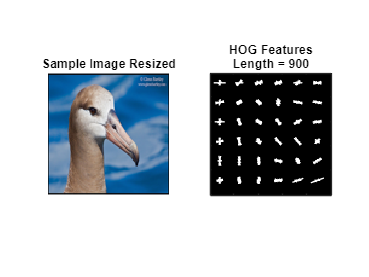

figure(1);
img = cdsTraining.read{1};
imgGray = rgb2gray(img);
[hogFeature, visualization] = extractHOGFeatures(imgGray, 'CellSize', [16 16]);
subplot(1, 2, 1);
imshow(img);
title('Sample Image Resized');
subplot(1, 2, 2);
plot(visualization);
title({'HOG Features'; ['Length = ' num2str(length(hogFeature))]});

## Extract HOG features


%% Extract HOG features from all images

cellSize = [16 16];
hogFeatureSize = length(hogFeature);

% Start by extracting HOG features from the training set. These features
% will be used to train the classifier.
% Loop over the trainingSet and extract HOG features from each image.

% Extract HOG features for training set
numTrainImages = numel(trainingImageDS_Resized.UnderlyingDatastores{1, 1}.Files);
trainingFeatures = zeros(numTrainImages, hogFeatureSize, 'single');
reset(cdsTraining);
for i = 1:numTrainImages
    imgFromDS = read(cdsTraining);
    imgGray = rgb2gray(imgFromDS{1});
    trainingFeatures(i, :) = extractHOGFeatures(imgGray, 'CellSize', cellSize);
end

% Extract HOG features for test set
numTestImages = numel(testImageDS_Resized.UnderlyingDatastores{1, 1}.Files);
testFeatures = zeros(numTestImages, hogFeatureSize, 'single');
reset(cdsTest);
for i = 1:numTestImages
    imgFromDS = read(cdsTest);
    imgGray = rgb2gray(imgFromDS{1});
    testFeatures(i, :) = extractHOGFeatures(imgGray, 'CellSize', cellSize);
end

% Apply z-score normalization to standardize features
trainingFeatures = zscore(trainingFeatures);
testFeatures = zscore(testFeatures);

## Move Feature Data to GPU

disp('Moving feature data to GPU...');

Moving feature data to GPU...


XtrainGPU = gpuArray(trainingFeatures);
XtestGPU = gpuArray(testFeatures);
Ytrain = trainingImageDS.Labels; % Labels stay on CPU
disp('Data moved to GPU.');

Data moved to GPU.


## Train a multi-class SVM

%% Train a Multiclass SVM on GPU using Best Hyperparameters from previous experiments

disp('Training SVM classifier on GPU with best hyperparameters...');

Training SVM classifier on GPU with best hyperparameters...



t = templateSVM(...
    'KernelFunction', 'gaussian', ...
    'BoxConstraint', 998.46, ...
    'KernelScale', 'auto', ...
    'Standardize', true, ...
    'Solver', 'SMO', ...
    'Verbose', 1); 

SVMClassifier = fitcecoc(XtrainGPU, Ytrain, ...
    'Learners', t, ...
    'Coding', 'onevsall');

|===================================================================================================================================|
|   Iteration  | Set  |   Set Size   |  Feasibility  |     Delta     |      KKT      |  Number of   |   Objective   |   Constraint  |
|              |      |              |      Gap      |    Gradient   |   Violation   |  Supp. Vec.  |               |   Violation   |
|===================================================================================================================================|
|            0 |active|         7057 |  9.999999e-01 |  2.000000e+00 |  1.000000e+00 |            0 |  0.000000e+00 |  0.000000e+00 |
|         1000 |active|         7057 |  6.309868e-01 |  4.802585e-03 |  2.498567e-03 |          593 | -1.422298e+02 | -1.267996e-06 |
|         1255 |active|         7057 |  2.695596e-01 |  9.939671e-04 |  5.055070e-04 |          599 | -1.422303e+02 | -1.373992e-06 |

 Exiting Active Set upon convergence due to DeltaGradient.
|=


disp('SVM training complete.');

SVM training complete.


## Test the accuracy on the test partition

disp('Predicting labels on GPU...');

Predicting labels on GPU...


YPredGPU = predict(SVMClassifier, XtestGPU);
YPred = gather(YPredGPU); % Bring predictions back to CPU
YTest = testImageDS.Labels;

% Calculate overall accuracy
accuracy = sum(YPred == YTest)/numel(YTest) % Output on command line

accuracy = 0.0610

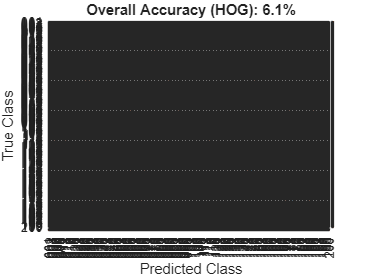


% Show confusion matrix in figure
[m, order] = confusionmat(YTest, YPred);
figure(2);
cm = confusionchart(m, order, ...
    'ColumnSummary','column-normalized', ...
    'RowSummary','row-normalized');
title("Overall Accuracy (HOG): "+ string(round(accuracy*100, 1)) +"%");